# Lazo cerrado (Control de Posición)

Ana Itzel Hernández García 

Limpieza de pantalla

clear all
close all
clc

Puntos deseados

x_vec = [22.3, 18.3, 14.5, 11, 5.4,  3.4,  0, -3.5, -3.5,  -11.2,  -11.2, -18.3, -18.4,-14.6,-3.6, 0, 0, 0, 3.6];
y_vec = [3.6, 3.6, 7.7, 11, 25.8, 22.3, 22.3, 26, 21, 18.41, 14.6, 14.6, 10, 3.5, 3.7, 0, -3.7, -11, -18.4];

**Contron Lazo Cerrado**

Tiempo de simulación y muestreo

tf = 10*length(x_vec);  % Tiempo total (s) de acuerdo a laos puntos
ts = 0.02;         % Tiempo de muestreo (s)
t = 0:ts:tf;
N = length(t);

Condiciones iniciales

x1(1) = x_vec(1);
y1(1) = y_vec(1);
phi(1) = 0;

Punto de control

hx(1) = x1(1);
hy(1) = y1(1);

Inicializamos vectores de velocidad

v = zeros(1, N);
w = zeros(1, N);
Error = zeros(1, N);

k_global = 1; % índice global para recorrer todo el vector de tiempo

% Bucle principal para recorrer todos los puntos de x_vec e y_vec
for i = 1:length(x_vec)

    hxd = x_vec(i);
    hyd = y_vec(i);

    while k_global < N
        % Errores de posición
        hxe(k_global) = hxd - hx(k_global);
        hye(k_global) = hyd - hy(k_global);
        Error(k_global) = sqrt(hxe(k_global)^2 + hye(k_global)^2);

        % Condición de llegada al punto
        if Error(k_global) < 0.17
            break;
        end

        % Jacobiano
        J = [cos(phi(k_global)) -sin(phi(k_global));
             sin(phi(k_global))  cos(phi(k_global))];

        % Ganancias
        K = [1 0;
             0 1];

        % Ley de control
        he = [hxe(k_global); hye(k_global)];
        qpRef = pinv(J) * K * he;
        v(k_global) = qpRef(1);
        w(k_global) = qpRef(2);

        % Actualización del estado
        phi(k_global + 1) = phi(k_global) + w(k_global) * ts;
        xp1 = v(k_global) * cos(phi(k_global));
        yp1 = v(k_global) * sin(phi(k_global));
        x1(k_global + 1) = x1(k_global) + xp1 * ts;
        y1(k_global + 1) = y1(k_global) + yp1 * ts;
        hx(k_global + 1) = x1(k_global + 1);
        hy(k_global + 1) = y1(k_global + 1);

        k_global = k_global + 1;
    end

end


 **SIMULACIÓN VIRTUAL **

Configuración de escena

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');

% Calcular rangos automáticamente basados en la trayectoria real
minX = min(x1) - 1;
maxX = max(x1) + 1;
minY = min(y1) - 1;
maxY = max(y1) + 1;

view(2); % Vista 2D
axis([minX maxX minY maxY 0 1]); % Rango ajustado a la trayectoria real

Límites automáticos

xmin_lim = min(x_vec) - 2;
xmax_lim = max(x_vec) + 2;
ymin_lim = min(y_vec) - 2;
ymax_lim = max(y_vec) + 2;
axis([xmin_lim xmax_lim ymin_lim ymax_lim 0 1]);

Gráfica inicial

scale = 4;
MobileRobot_5; 
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
H3 = plot3(x_vec, y_vec, 0 * ones(size(x_vec)), 'bo', 'lineWidth', 2);
H4 = plot3(hx(1), hy(1), 0, 'go', 'lineWidth', 2);

Animación

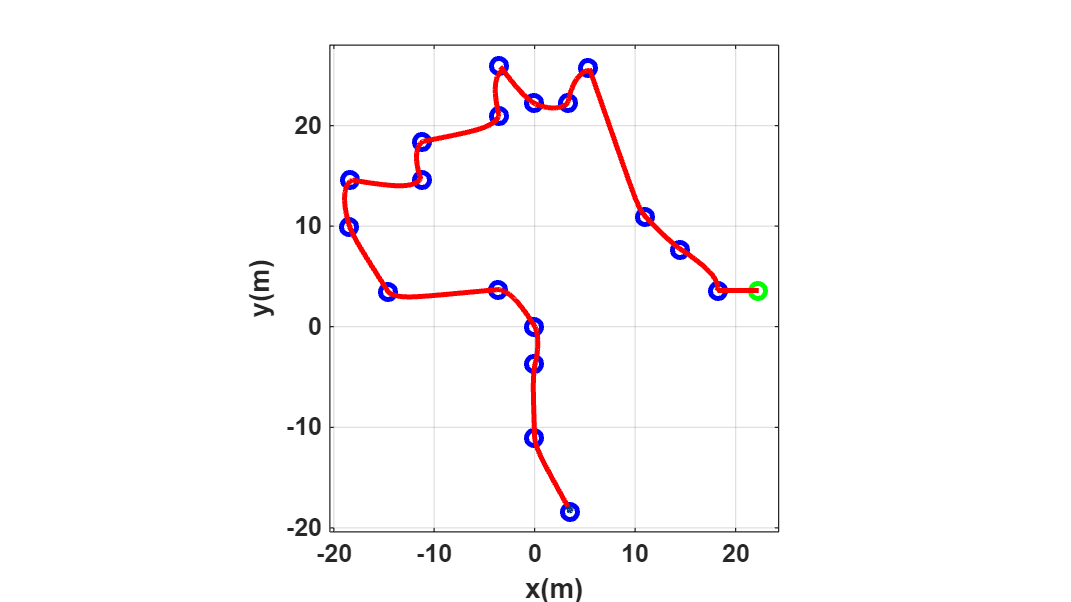

step = 1;
for k = 1:step:k_global
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

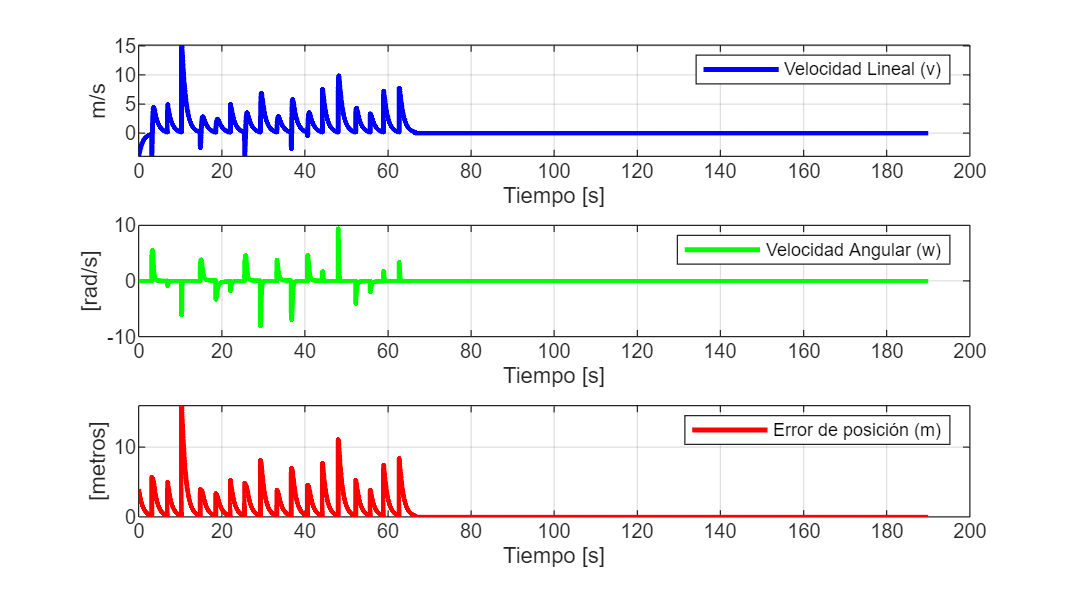

graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');